% load data from .npy files
clear;
trainFolder = 'trainRecord_anti_R_5_1';


b1 = readNPY(sprintf('data/%s/b1.npy',trainFolder));
b2 = readNPY(sprintf('data/%s/b2.npy',trainFolder));
eta = readNPY(sprintf('data/%s/eta.npy',trainFolder));
lambda = readNPY(sprintf('data/%s/lambda.npy',trainFolder));
w1 = readNPY(sprintf('data/%s/w1.npy',trainFolder));
w2 = readNPY(sprintf('data/%s/w2.npy',trainFolder));
train_data = squeeze(readNPY(sprintf('data/%s/train_data.npy',trainFolder)));
train_label = readNPY(sprintf('data/%s/train_label.npy',trainFolder));
valid_data = readNPY(sprintf('data/%s/valid_data.npy',trainFolder));
valid_label = readNPY(sprintf('data/%s/valid_label.npy',trainFolder));


% construct middle state and correlation matrix
% d: input dim, N: hidden dim
R = 5;
[T,d] = size(train_data);
N = size(w2,3);
num_epoch = size(b1,1);
freq = nanmean(valid_label);


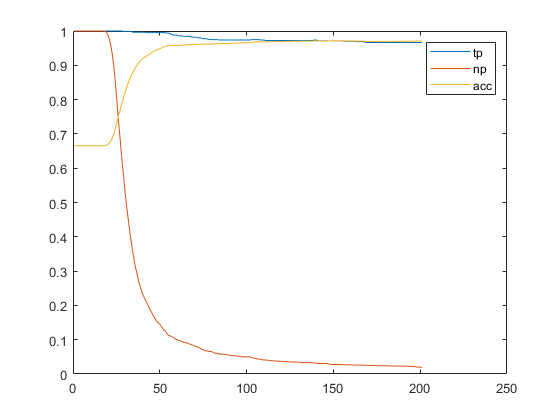

% verify the epoch model
A = zeros(d,N,T+1,num_epoch);
h = zeros(N,T,num_epoch);
a = zeros(N,T,num_epoch);
yhat = zeros(T,num_epoch);
ylabel = zeros(T,num_epoch);
acc_tp = zeros(num_epoch,1);
acc_np = zeros(num_epoch,1);
acc = zeros(num_epoch,1);


for epoch = 1:num_epoch
    b1_epoch = b1(epoch,:)';
    b2_epoch = b2(epoch,:);
    eta_epoch = eta(epoch,:);
    lambda_epoch = lambda(epoch,:);
    w1_epoch = squeeze(w1(epoch,:,:));
    w2_epoch = squeeze(w2(epoch,:,:));
    for t = 1:T
        At = squeeze(A(:,:,t,epoch));
        xt = valid_data(t,:)';
        at = (w1_epoch + At')*xt + b1_epoch;
        ht = sigma(at);
        a(:,t,epoch) = at;
        h(:,t,epoch) = ht;
        A(:,:,t+1,epoch) = lambda_epoch * At + eta_epoch*xt*ht';
        yhat(t,epoch) = sigma(w2_epoch'*ht+b2_epoch);
    end
    ylabel(:,epoch) = yhat(:,epoch) > 1/2;
    acc_tp(epoch) = nanmean(ylabel(valid_label==1, epoch));
    acc_np(epoch) = nanmean(ylabel(valid_label==0, epoch));
    acc(epoch) = (1-freq)*acc_tp(epoch) + freq*(1-acc_np(epoch));
end

figure; 
plot(acc_tp);hold on; plot(acc_np);hold on; plot(acc);legend({'tp','np','acc'});


allegianceMatrix = cell(120,1);

for i = 1:120
    i
    % Preallocate the allegianceMatrix
    allegianceMatrix{i} = zeros(120, 120, 101);
    
    for j = 1:101
        % Get the S matrix from dataFile_R_5_rep_120_diff_data for current i and j
        S = dataFile_R_5_rep_120_diff_data{i}.S{j};
        
        % Compute a logical matrix with the size of 120x50x120, where each element
        % (s,:,t) is true if S(s,:) is equal to S(t,:)
        logicalMatrix = bsxfun(@eq, S, permute(S, [3, 2, 1]));
        
        % Compute the nanmean of logicalMatrix along the second dimension (columns)
        logicalMatrixMean = nanmean(logicalMatrix, 2);
        
        % Squeeze the second dimension out, resulting in a 120x120 matrix
        logicalMatrixMeanSqueezed = squeeze(logicalMatrixMean);
        
        % Add the logicalMatrixMeanSqueezed to the allegianceMatrix
        allegianceMatrix{i}(:,:,j) = allegianceMatrix{i}(:,:,j) + logicalMatrixMeanSqueezed;
    end
end
